# Solución Puntos

## P5.3

P5Considerando el robot asignado, construya el modelo del robot utilizando RST

!) asignación sistemas de coordenadas

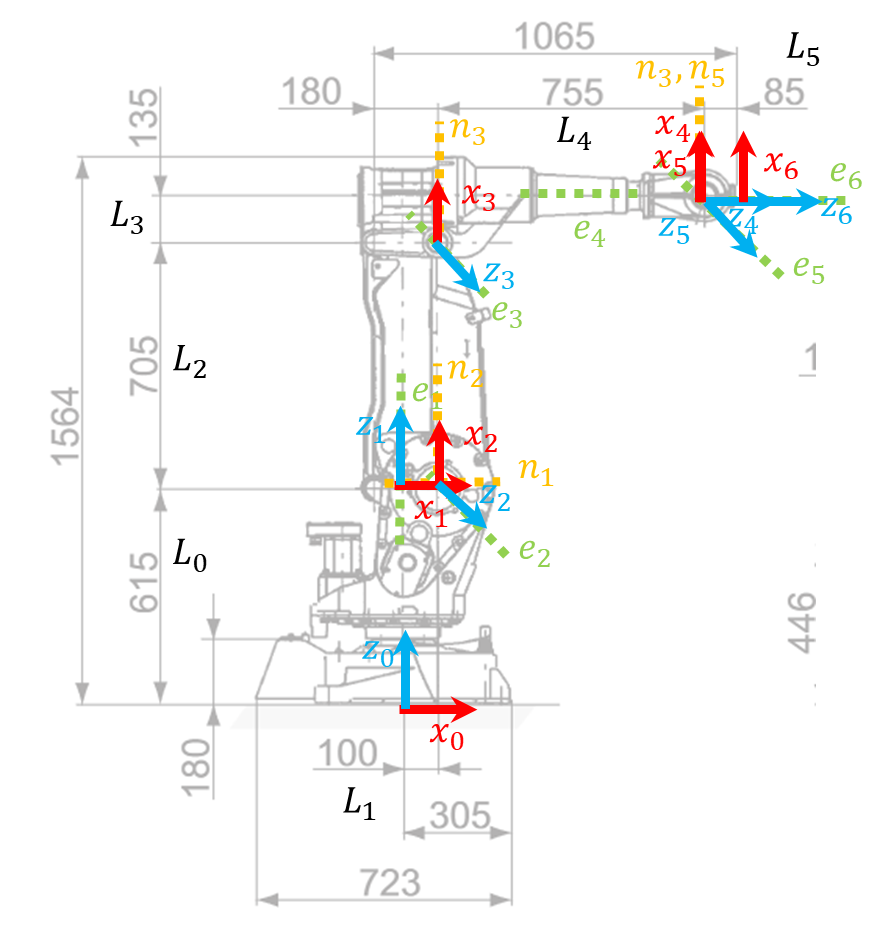

2) Parámetros DHmod

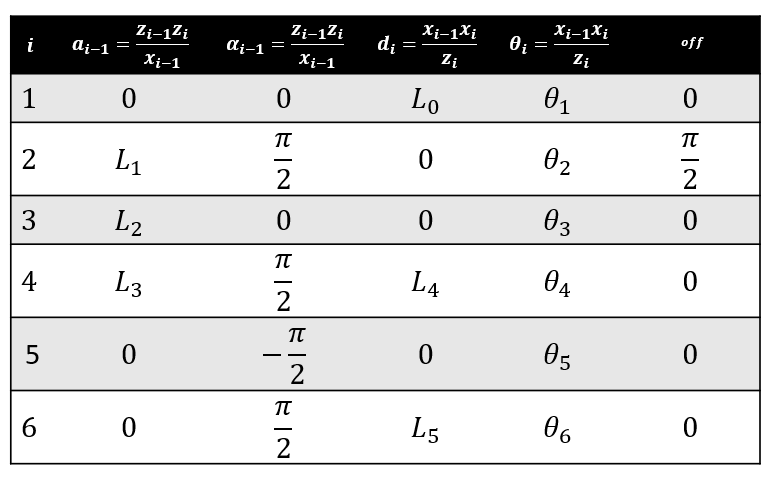

3) Usando Robotics System Toolbox, se obtiene el modelo de la siguiente manera

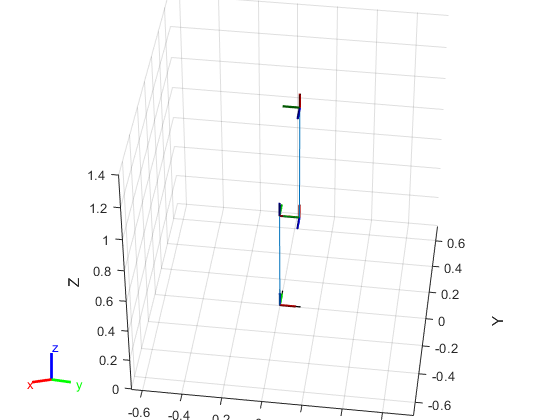

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


clear all;clf;clc;

robot = rigidBodyTree('DataFormat','column','MaxNumBodies',6);

L0 = 0.615;
L1 = 0.1;
L2 = 0.705;
L3 = 0.135;
L4 = 0.755;
L5 = 0.085;

% Se agrega Eslabón1 - Articulación1
body = rigidBody('link1');
joint = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(joint,trvec2tform([0 0 0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'base');

% Se agrega Eslabón2 - Articulación2
body = rigidBody('link2');
joint = rigidBodyJoint('joint2','revolute');
setFixedTransform(joint, trvec2tform([0,0,L0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link1');

% Se agrega Eslabón3 - Articulación3
body = rigidBody('link3');
joint = rigidBodyJoint('joint3','revolute');
setFixedTransform(joint, trvec2tform([L1,0,0])*eul2tform([pi/2 0 pi/2],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link2');

% Se agrega Eslabón4 - Articulación4
body = rigidBody('link4');
joint = rigidBodyJoint('joint4','revolute');
setFixedTransform(joint, trvec2tform([L2,0,0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link3');


show(robot)
axis auto

% % Se agrega Eslabón5 - Articulación5
% body = rigidBody('link5');
% joint = rigidBodyJoint('joint5','revolute');
% setFixedTransform(joint, trvec2tform([L1,0,0]));
% joint.JointAxis = [0 0 1];
% body.Joint = joint;
% addBody(robot, body, 'link4');
% 
% % Se agrega Eslabón2 - Articulación2
% body = rigidBody('link6');
% joint = rigidBodyJoint('joint6','revolute');
% setFixedTransform(joint, trvec2tform([L1,0,0]));
% joint.JointAxis = [0 0 1];
% body.Joint = joint;
% addBody(robot, body, 'link5');